# Simulations

## First order SDT

The first model that we consider is an unequal variance Signal Detection Theory (uv-SDT) model, with higher variance for the signal distribution.

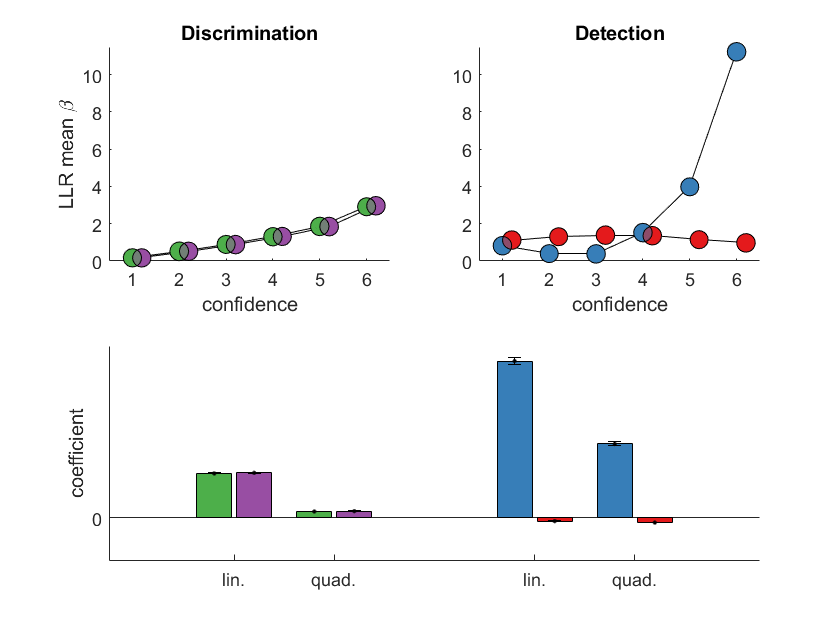

rng(1); %for reproducibility

% Discrimination:
% initialize response count matrices.
trial_count.C_num_trials = [];
trial_count.A_num_trials = [];

% initialize simulated beta matrices.
simulation_betas.conf_A = [];
simulation_betas.conf_C = [];

% Detection:
% initialize response count matrices.
trial_count.Y_num_trials = [];
trial_count.N_num_trials = [];

% initialize simulated beta matrices.
simulation_betas.conf_Y = [];
simulation_betas.conf_N = [];


for i_s = 1:35 %simulate 35 participants
    
    % DISCRIMINATION
    
    % the 'clockwise' and 'counterclockwise' distributions are symmetric
    % around 0.
    dis.mu = binornd(1,0.5,200,1)-0.5;
    
    % sampled from a normal distribution with sigma = 1.
    dis.samples = normrnd(dis.mu,1);
    
    % compute likelihood under both hypotheses and extract Log Likelihood
    % Ratio (LLR)
    dis.likelihood1 = normpdf(dis.samples,-0.5,1);
    dis.likelihood2 = normpdf(dis.samples,0.5,1);
    dis.LLR = log2(dis.likelihood1./dis.likelihood2);
    
    % respond 1 if clockwise and 0 if counterclockwise
    dis.resp = dis.LLR>0;
    
    % technical detail: confidence scales with distance from the decision
    % boundary, assuming a uniform distribution of confidence ratings over
    % the 6 bins.
    dis.edges  = prctile(abs(dis.samples),100/6*[0:6]);
    dis.conf = discretize(abs(dis.samples),dis.edges);
    
    % update trial counts and simulated betas.
    for i_conf = 1:6
        trial_count.C_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==0);
        trial_count.A_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==1);
        
        % beta values are LLR
        simulation_betas.conf_C(i_s,i_conf) = ...
            nanmean(abs(dis.LLR(dis.conf==i_conf & dis.resp==0)));
        simulation_betas.conf_A(i_s,i_conf) = ...
            nanmean(abs(dis.LLR(dis.conf==i_conf & dis.resp==1)));
    end
    
    % DETECTION
    
    % the 'noise' distribution is centred around 0 with sigma=1. The
    % 'signal distribution is centred around 1.3 with sigma=2.
    det.mu = binornd(1,0.5,200,1);
    det.samples = normrnd(det.mu*1.3,(1+det.mu)); %unequal variance
    
    % compute likelihood under both hypotheses and extract Log Likelihood
    % Ratio (LLR)
    det.likelihood1 = normpdf(det.samples,1.3,2);
    det.likelihood2 = normpdf(det.samples,0,1);
    det.LLR = log2(det.likelihood1./det.likelihood2);
    
    % Important detail: the decision criterion is fixed to make sure that
    % 50% of responses are 'yes' and 50% are 'no.
    det.resp = det.samples>median(det.samples);
    
    % technical detail: confidence scales with distance from the decision
    % boundary, assuming a uniform distribution of confidence ratings over
    % the 6 bins. Unlike discrimination, here it is done separately for the
    % two responses.
    det.yes_edges  = prctile(det.samples(det.resp)-median(det.samples),100/6*[0:6]);
    det.conf = discretize(det.samples-median(det.samples),det.yes_edges);
    det.no_edges  = prctile(median(det.samples)-det.samples(~det.resp),100/6*[0:6]);
    det.conf(~det.resp) = discretize(median(det.samples)-det.samples(~det.resp),det.no_edges);
    
    % update trial counts and simulated betas.
    for i_conf = 1:6
        trial_count.N_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==0);
        trial_count.Y_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==1);
        
        % beta values are LLR
        simulation_betas.conf_N(i_s,i_conf) = ...
            nanmean(abs(det.LLR(det.conf==i_conf & det.resp==0)));
        simulation_betas.conf_Y(i_s,i_conf) = ...
            nanmean(abs(det.LLR(det.conf==i_conf & det.resp==1)));
    end
    

end
% plot
simulation_name = 'LLR';
plotQuadFit(trial_count, simulation_betas,simulation_name);

Classical unequal variance predicts a different pattern from the observed one, with different confidence profiles for 'yes' and for 'no' responses. The next model is a more sophisticated model that assumes a latent attentional state to which the participant has only indirect access, and that affects perception. Neural activation is assumed to be proportional to prior beliefs about this latent state.

## Counterfactual reasoning / attention monitoring

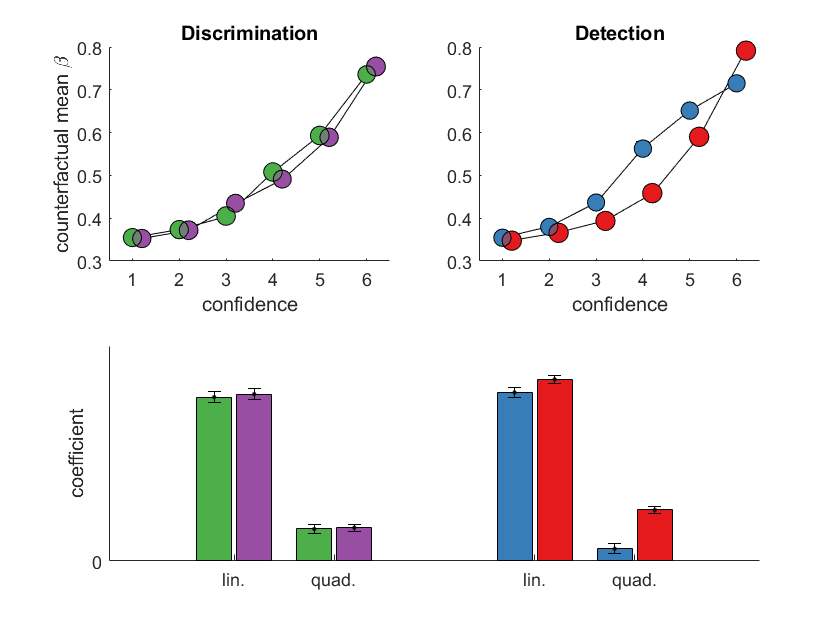

rng(1); %for reproducibility

% Discrimination:
% initialize response count matrices.
trial_count.C_num_trials = [];
trial_count.A_num_trials = [];

% initialize simulated beta matrices.
simulation_betas.conf_A = [];
simulation_betas.conf_C = [];

% Detection:
% initialize response count matrices.
trial_count.Y_num_trials = [];
trial_count.N_num_trials = [];

% initialize simulated beta matrices.
simulation_betas.conf_Y = [];
simulation_betas.conf_N = [];

dis_acc = [];
det_acc = [];

for i_s = 1:35 %simulate 35 participants
    
    % DISCRIMINATION
    
    % 'attended' is a binary variable that reflects a cartoon attention
    % state (attended or not). Importantly, the agent has no direct access
    % ot the value of this variable, but only probabilistically through the
    % onTask variable.
    dis.attended = binornd(1,0.5,200,1);
    
    % The onTask variable can take any value between 0 and 1. 0 reflects
    % strng belief in that I did not pay attention, and 1 reflects strong
    % blief in that I did pay attention. 
    dis.onTask = betarnd(1+dis.attended, 2-dis.attended,200,1); 
    
    % the 'clockwise' and 'counterclockwise' distributions are symmetric
    % around 0.
    dis.mu = 0.5*(binornd(1,0.5,200,1)-0.5);
    
    % but are farther away from 0 on 'attended' trials.
    dis.mu(logical(dis.attended)) = 4*dis.mu(logical(dis.attended));
    
    % sampled from a normal distribution with sigma = 1.
    dis.samples = normrnd(dis.mu,1);
    
    % compute likelihoods under both hypotheses and extract LLR.
    dis.likelihood1 = dis.onTask.*normpdf(dis.samples,0.5*0.5*4,1)+...
        (1-dis.onTask).*normpdf(dis.samples,0.5*0.5,1);
    dis.likelihood2 = dis.onTask.*normpdf(dis.samples,0.5*(-0.5)*4,1)+...
        (1-dis.onTask).*normpdf(dis.samples,0.5*(-0.5),1);    
    dis.LLR = log2(dis.likelihood1./dis.likelihood2);
    
    % respond 1 if 'clockwise', 0 if 'counterclockwise'.
    dis.resp = dis.LLR>0;
    
    % technical detail: confidence scales with distance from the decision
    % boundary, assuming a uniform distribution of confidence ratings over
    % the 6 bins.
    dis.edges  = prctile(abs(dis.LLR),100/6*[0:6]);
    dis.conf = discretize(abs(dis.LLR),dis.edges);
    
    % update trial counts and simulated betas.
    for i_conf = 1:6
        trial_count.C_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==0);
        trial_count.A_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==1);
        
        % beta values are onTask values.
        simulation_betas.conf_C(i_s,i_conf) = ...
            nanmean(dis.onTask(dis.conf==i_conf & dis.resp==0));
        simulation_betas.conf_A(i_s,i_conf) = ...
            nanmean(dis.onTask(dis.conf==i_conf & dis.resp==1));
    end
    dis_acc(end+1,:) = [nanmean(dis.resp==sign(dis.mu)/2+0.5)...
        nanmean(dis.resp(dis.attended==1)==sign(dis.mu(dis.attended==1))/2+0.5)...
        nanmean(dis.resp(dis.attended==0)==sign(dis.mu(dis.attended==0))/2+0.5)];
    
    % DETECTION
    det.attended = binornd(1,0.5,200,1); %same as in discrimination
    det.onTask = betarnd(1+det.attended, 2-det.attended,200,1); %same as in discrimination
    det.mu = binornd(1,0.5,200,1)/2;
    % mu for noise trials is alway 0. mu for signal trials is dependent on
    % attentional state: 0.5 if not attending and 2 if attending. Note that
    % in effect, this renders the 'signal' distribution wider than the
    % 'noise' distribution.
    det.mu(logical(det.attended)) = det.mu(logical(det.attended))*4;
    % sampled from a normal distribution with sigma = 1.
    det.samples = normrnd(det.mu,1); 
    
    % compute likelihoods under both hypotheses and extract LLR.
    det.likelihood1 = det.onTask.*normpdf(det.samples,2,1)+...
        (1-det.onTask).*normpdf(det.samples,0.5,1);
    det.likelihood2 = det.onTask.*normpdf(det.samples,0,1)+...
        (1-det.onTask).*normpdf(det.samples,0,1);
    det.LLR = log2(det.likelihood1./det.likelihood2);
    
    % respond 1 if 'yes', 0 if 'no'.
    det.resp = det.LLR>0;
    
    % technical detail: confidence scales with distance from the decision
    % boundary, assuming a uniform distribution of confidence ratings over
    % the 6 bins. Unlike discrimination, here it is done separately for the
    % two responses.
    det.yes_edges  = prctile(det.LLR(det.resp),100/6*[0:6]);
    det.conf = discretize(det.LLR,det.yes_edges);
    det.no_edges  = prctile(-det.LLR(~det.resp),100/6*[0:6]);
    det.conf(~det.resp) = discretize(-det.LLR(~det.resp),det.no_edges);
    
    % update trial counts and simulated betas.
    for i_conf = 1:6
        trial_count.N_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==0);
        trial_count.Y_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==1);
        
        % beta values are onTask.    
        simulation_betas.conf_N(i_s,i_conf) = ...
            nanmean(det.onTask(det.conf==i_conf & det.resp==0));
        simulation_betas.conf_Y(i_s,i_conf) = ...
            nanmean(det.onTask(det.conf==i_conf & det.resp==1));
    end
    det_acc(end+1,:) = [nanmean(det.resp==sign(det.mu))...
        nanmean(det.resp(det.attended==1)==sign(det.mu(det.attended==1)))...
        nanmean(det.resp(det.attended==0)==sign(det.mu(det.attended==0)))]  ;
    
end

% plot
simulation_name = 'counterfactual';
plotQuadFit(trial_count, simulation_betas,simulation_name);

The counterfactual model predicts a difference between 'yes' and 'no' responses in both the linear and (less so) quadratic effects of confidence. While this may explain the rTPJ pattern, this model fails to explain the patterns in the FPC, STS and pre-SMA, where 'yes' and 'no' responses behave similarly, but different from discrimination. The next model that we consider is a dynamic model, in which beliefs about the hidden parameters controlling the location and spread of the four distributions are monitored throughout the experiment, and are in turn affecting the position of the decision variable. BOLD signal here is assumed to be proportional to the extent to which the decision criterion needs to move after seeing the current sample.

## Dynamic criterion placement

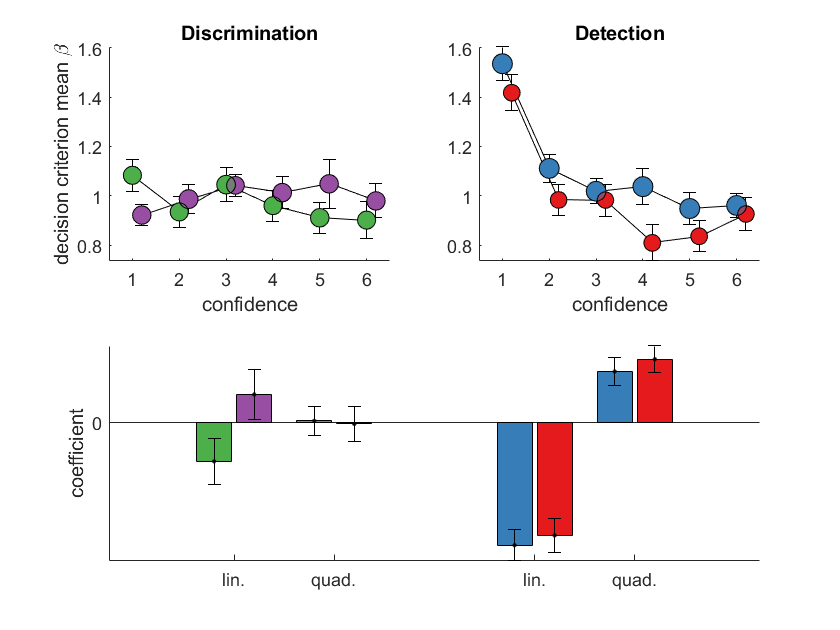

rng(1); %for reproducibility

% Discrimination:
% initialize response count matrices.
trial_count.C_num_trials = [];
trial_count.A_num_trials = [];

% initialize simulated beta matrices.
simulation_betas.conf_A = [];
simulation_betas.conf_C = [];

% Detection:
% initialize response count matrices.
trial_count.Y_num_trials = [];
trial_count.N_num_trials = [];

% initialize simulated beta matrices.
simulation_betas.conf_Y = [];
simulation_betas.conf_N = [];

% this grid is used later to find the optimal position for the decision
% criterion. 
x_grid = 5:-0.01:-5;

for i_s = 1:35 %simulate 35 participants
    
    %% DISCRIMINATION
    %for this model, we assume that prior beliefs about the clockwise and
    %anticlockwise distributions are represented as a small number of
    %hypothetical samples from these distributions. 
    sample_C = normrnd(0.5,1,5,1);
    sample_A = normrnd(-0.5,1,5,1);
    
    % the 'clockwise' and 'counterclockwise' distributions are symmetric
    % around 0.
    dis.mu = binornd(1,0.5,200,1)-0.5;
    % samples are sampled from a normal distribution with sigma=1
    dis.samples = normrnd(dis.mu,1);
    
    % initialize vectors with nans
    dis.mu_C_est = nan(size(dis.mu));
    dis.mu_A_est = nan(size(dis.mu));

    dis.sigma_C_est = nan(size(dis.mu));
    dis.sigma_A_est = nan(size(dis.mu));

    dis.likelihood_C = nan(size(dis.mu));
    dis.likelihood_A = nan(size(dis.mu));
    
    dis.criterion_shift = nan(size(dis.mu));
    dis.LLR = nan(size(dis.mu));

    dis.resp = nan(size(dis.mu));
    
    dis.criterion = nan(size(dis.mu));
    
    % loop over trials
    for i = 1:length(dis.mu)
        
        % current belief about mu and sigma of 'clockwise'
        % distribution is the mean and standard deviation of my sample.
        dis.mu_C_est(i) = mean(sample_C);
        dis.sigma_C_est(i) = std(sample_C);
        
        % current belief about mu and sigma of 'clockwise'
        % distribution is the mean and standard deviation of my sample.
        dis.mu_A_est(i) = mean([sample_A]);
        dis.sigma_A_est(i) = std([sample_A]);
        
        dis.LLR(i) = log2(normpdf(dis.samples(i),dis.mu_C_est(i), dis.sigma_C_est(i))./...
            normpdf(dis.samples(i),dis.mu_A_est(i), dis.sigma_A_est(i)));
        
        % the criterion is the rightmost point in which the likelihood of
        % the two hypotheses is equal (i.e., LLR=0). I use grid estimation
        % to find this point to avoid complex computations. 
        LLR_vec = log2(normpdf(x_grid,dis.mu_C_est(i), dis.sigma_C_est(i))./...
            normpdf(x_grid,dis.mu_A_est(i), dis.sigma_A_est(i)));
        dis.criterion(i) = x_grid(abs(LLR_vec)==min(abs(LLR_vec)));
        % The experiment is comprised of blocks of 40 trials. 
        if mod(i,40)~=1
            % the criterion shift for trial i-1 is the distance between the
            % previous and the current decision criterion placements.
            dis.criterion_shift(i-1) = abs(dis.criterion(i)-dis.criterion(i-1));
        end
        
        % respond 'clockwise' if the sample falls to the right of the
        % criterion. Otherwise, respond 'counterclockwise'.
        dis.resp(i) = dis.samples(i)>dis.criterion(i);
        
        % update samples. At each timepoint only the last 5 samples of each
        % category are saved and used for estimation of mu and sigma.
        if dis.resp(i)==1 %decided clockwise
            sample_C = [sample_C(2:end);dis.samples(i)];
        else %decided counter clockwise
           sample_A = [sample_A(2:end); dis.samples(i)];
        end
        
    end
   
    % technical detail: confidence scales with distance from the decision
    % boundary, assuming a uniform distribution of confidence ratings over
    % the 6 bins.
    dis.edges  = prctile(abs(dis.LLR),100/6*[0:6]);
    dis.conf = discretize(abs(dis.LLR),dis.edges);
    
    % update trial counts and simulated betas.
    for i_conf = 1:6
        trial_count.C_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==0);
        trial_count.A_num_trials(i_s,i_conf) = ...
            sum(dis.conf==i_conf & dis.resp==1);
        
        % beta is criterion_shift
        simulation_betas.conf_C(i_s,i_conf) = ...
            nanmean(dis.criterion_shift(dis.conf==i_conf & dis.resp==0));
        simulation_betas.conf_A(i_s,i_conf) = ...
            nanmean(dis.criterion_shift(dis.conf==i_conf & dis.resp==1));
    end
    
    %% DETECTION
    %for this model, we assume that prior beliefs about the signal and
    %noise distributions are represented as a small number of
    %hypothetical samples from these distributions. 
    sample_Y = normrnd(1,1.3,5,1);
    sample_N = normrnd(0,1,5,1);
    
    % the 'noise' distribution is centred around 0 with sigma=1. The
    % 'signal distribution is centred around 1.3 with sigma=2.
    det.mu = binornd(1,0.5,200,1);
    det.samples = normrnd(1.3*det.mu,1+0.3*(det.mu-0.5)); %unequal variance
    
    % initialize vectors with nans
    det.mu_Y_est = nan(size(det.mu));
    det.mu_N_est = nan(size(det.mu));

    det.sigma_Y_est = nan(size(det.mu));
    det.sigma_N_est = nan(size(det.mu));

    det.likelihood_Y = nan(size(det.mu));
    det.likelihood_N = nan(size(det.mu));
    
    det.criterion_shift = nan(size(det.mu));
    det.LLR = nan(size(det.mu));

    det.resp = nan(size(det.mu));

    % loop over trials
    for i = 1:length(det.mu)
        
        % current belief about mu and sigma of the signal
        % distribution is the mean and standard deviation of my sample.
        det.mu_Y_est(i) = mean(sample_Y);
        det.sigma_Y_est(i) = std(sample_Y);

        % current belief about mu and sigma of the noise
        % distribution is the mean and standard deviation of my sample.
        det.mu_N_est(i) = mean(sample_N);
        det.sigma_N_est(i) = std(sample_N);
        
        det.LLR(i) = log2(normpdf(det.samples(i),det.mu_Y_est(i), det.sigma_Y_est(i))./...
            normpdf(det.samples(i),det.mu_N_est(i), det.sigma_N_est(i)));
        
        % the criterion is the rightmost point in which the likelihood of
        % the two hypotheses is equal (i.e., LLR=0). I use grid estimation
        % to find this point to avoid complex computations. 
        LLR_vec = log2(normpdf(x_grid,det.mu_Y_est(i), det.sigma_Y_est(i))./...
            normpdf(x_grid,det.mu_N_est(i), det.sigma_N_est(i)));
        det.criterion(i) = x_grid(abs(LLR_vec)==min(abs(LLR_vec)));
        
        %The experiment is comprised of blocks of 40 trials. 
        if mod(i,40)~=1
            % the criterion shift for trial i-1 is the distance between the
            % previous and the current decision criterion placements.
            det.criterion_shift(i-1) = abs(det.criterion(i)-det.criterion(i-1));
        end
        
        % respond 'yes' if the sample falls to the right of the
        % criterion. Otherwise, respond 'no'.
        det.resp(i) = det.samples(i)>det.criterion(i);
        
        % update samples. At each timepoint only the last 5 samples of each
        % category are saved and used for estimation of mu and sigma.
        if det.resp(i)==1 %decided present
            sample_Y = [sample_Y(2:end);det.samples(i)];
        else %decided absent
           sample_N = [sample_N(2:end); det.samples(i)];
        end
        
    end
   
    % technical detail: confidence scales with distance from the decision
    % boundary, assuming a uniform distribution of confidence ratings over
    % the 6 bins. Unlike discrimination, here it is done separately for the
    % two responses.
    det.yes_edges  = prctile(det.LLR(det.resp==1),100/6*[0:6]);
    det.conf = discretize(det.LLR,det.yes_edges);
    det.no_edges  = prctile(-det.LLR(det.resp==0),100/6*[0:6]);
    det.conf(det.resp==0) = discretize(-det.LLR(det.resp==0),det.no_edges);
    
    % update trial counts and simulated betas.
    for i_conf = 1:6
        trial_count.N_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==0);
        trial_count.Y_num_trials(i_s,i_conf) = ...
            sum(det.conf==i_conf & det.resp==1);
        
        % beta values are criterion_shift
        simulation_betas.conf_N(i_s,i_conf) = ...
            nanmean(det.criterion_shift(det.conf==i_conf & det.resp==0));
        simulation_betas.conf_Y(i_s,i_conf) = ...
            nanmean(det.criterion_shift(det.conf==i_conf & det.resp==1));
    end
end

%plot  
simulation_name = 'decision criterion';
plotQuadFit(trial_count, simulation_betas,simulation_name);